# HDG scheme to Box potential

#### Un método de Galerkin Discontinuo Hibridizable para la ecuación de Schrödinger estacionaria lineal

Resultados de ejemplos de *@alujan*

clear
format short
syms x y z real

% Let's add to the path the src and drivers: Original Article
addpath('./src/')

% Let's add the path of the gmsh structure: Load Mesh structure
addpath('./mesh/')

## 0. Preliminaries

Load of structures and previous definitions.

#### Load of structures for analisys

Let's load the reference structres we're going to use to set the pilot example

% Importing of a singular structure for first case scenario: Unitary cube
T = load_mesh('pi-cubeD3.msh')

T = struct with fields:
    coordinates: [873×3 double]
       elements: [3386×4 double]
      dirichlet: [1180×3 double]
        neumann: [0×3 double]
          faces: [7362×4 double]
       dirfaces: [6183 6184 6185 6186 6187 6188 6189 6190 6191 6192 6193 6194 6195 6196 6197 6198 6199 6200 6201 6202 6203 6204 6205 6206 6207 6208 6209 6210 6211 6212 6213 6214 6215 6216 6217 6218 6219 6220 6221 6222 6223 6224 6225 … ] (1×1180 double)
       neufaces: [1×0 double]
      facebyele: [3386×4 double]
    orientation: [3386×4 double]
           perm: [3386×4 double]
         volume: [3386×1 double]
           area: [7362×1 double]
        normals: [3386×12 double]


% Listing of elements for growth of method testing
listT = {T};

## 1. Construction of the scheme

Definition of the equation and the main elements needed to interact and create the solutions.

#### Definitions of reference solutions

First let's define the values we're going to compare with, in this case the functions $u$ and $\mathit{\mathbf{q}}$, defined for the auxiliar equation, it's important to notice that for instance $\psi$corresponds to the wave function of the particle and $J$ to the complex conjugate of the kinetic momentum operator applied to the wave function

                                               
$$\nabla u\left(\mathit{\mathbf{r}}\right)+\mathit{\mathbf{q}}\left(\mathit{\mathbf{r}}\right)=0\;\textrm{in}\;\Omega$$


                                                    
$$-\textrm{div}\;\mathit{\mathbf{q}}\left(\mathit{\mathbf{r}}\right)=\lambda \;u\left(\mathit{\mathbf{r}}\right)\;\textrm{in}\;\Omega$$


                                                             
$$u\left(\mathit{\mathbf{r}}\right)=0\;\textrm{on}\;\partial \Omega$$


Take in mind this a scalar PDE, for this scenario every evaluation of the values must be in components of the vector.

% Let's define a simple value for U: harmonic vector
% - Caracteristics of the function in space
U(x, y, z) = sin(x)*sin(y)*sin(z)

$$U(x, y, z) = \sin\left(x\right)\,\sin\left(y\right)\,\sin\left(z\right)$$

% Partial derivarives of the component
Ux = diff(U, x); Uxx = diff(U, x, 2);
Uy = diff(U, y); Uyy = diff(U, y, 2);
Uz = diff(U, z); Uzz = diff(U, z, 2);

Q = -[Ux; Uy; Uz]   % Gradient definition

$$Q(x, y, z) = \left(\begin{array}{c} -\cos\left(x\right)\,\sin\left(y\right)\,\sin\left(z\right)\\ -\cos\left(y\right)\,\sin\left(x\right)\,\sin\left(z\right)\\ -\cos\left(z\right)\,\sin\left(x\right)\,\sin\left(y\right) \end{array}\right)$$

% Definition of potential taking action
F(x, y, z) = - (Uxx + Uyy +Uzz)

$$F(x, y, z) = 3\,\sin\left(x\right)\,\sin\left(y\right)\,\sin\left(z\right)$$

% Processing of functions
u = matlabFunction(U, Vars={x, y, z});

qx = matlabFunction(-Ux, Vars={x, y, z});
qy = matlabFunction(-Uy, Vars={x, y, z});
qz = matlabFunction(-Uz, Vars={x, y, z});

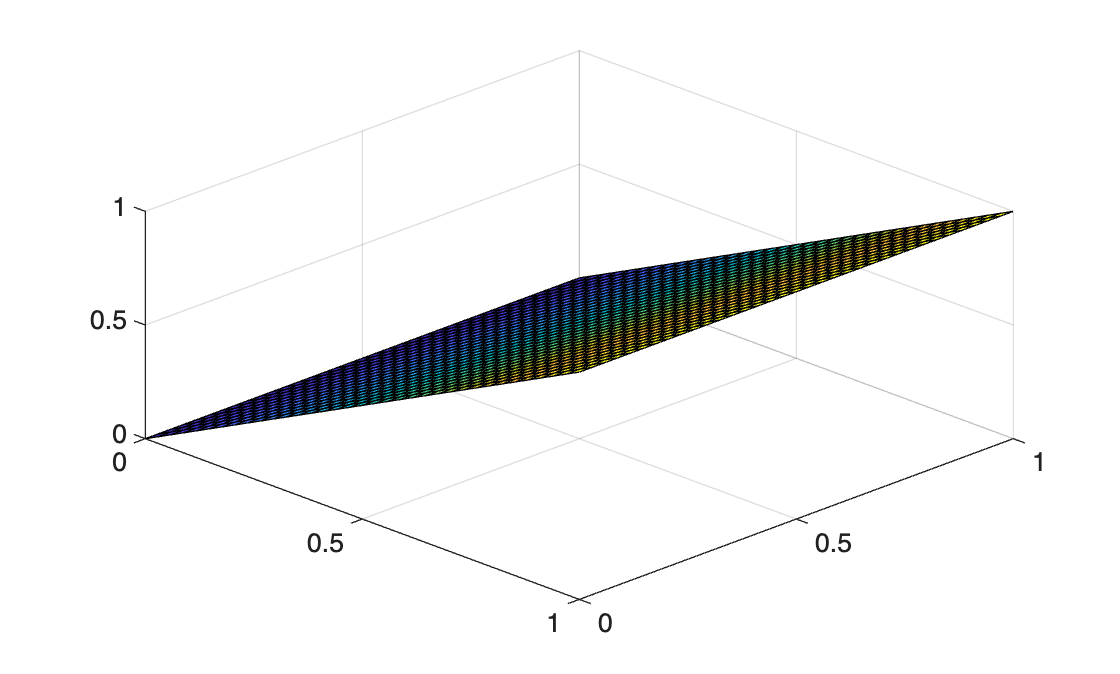

% Validation of dirichlet condition
clf('reset')

% Plot of conditions Null conditions for psi {x, y, z}
fig = figure; theme(fig,"auto");
hold on
fsurf(@(x, y) u(  x,   y,   0), [0 1 0 1])     % Condition for z = 0
fsurf(@(x, y) u(  x,   y,   pi), [0 1 0 1])     % Condition for z = pi
fsurf(@(x, z) u(  x,   0,   z), [0 1 0 1])     % Condition for y = 0
fsurf(@(x, z) u(  x,   pi,   z), [0 1 0 1])     % Condition for y = pi
fsurf(@(y, z) u(  0,   y,   z), [0 1 0 1])     % Condition for x = 0
fsurf(@(y, z) u(  pi,   y,   z), [0 1 0 1])     % Condition for x = pi

hold off
grid on
view([45, 45])

#### Definition of Cuadrature and Polynomial degrees

Now for the first definitions for the method, we must import the cuadrature that's going to be used, and the polynomial degree that's going to be used for the solution

% It's possible to change the values below to alter the polynomial and
% cuadrature precision for more general viewing
TablesQuadForm3d        % Importing of cuadrature for thetrahedron
TablesQuadForm          % Importing of cuadrature for triangles

k = 1;  % Polynomial Degree

% Switch case for the selection of formulas: cuadratures
switch k
    case 0 
        formulas={tetra3,tetra1,matrix0,matrix4};
    case 1
        formulas={tetra5,tetra3,matrix4,matrix9};
    case 2
        formulas={tetra7,tetra5,matrix9,matrix11};
    case 3
        formulas={tetra9,tetra7,matrix11,matrix14};
    case 4
        formulas={tetra9,tetra9,matrix14,matrix16};
end

% Reduction of weights: Sum of weights it's defined to be equal to 2, for
% normalization it's reduced to 1.
formulas{3}(:,4)=formulas{3}(:,4)/2;
formulas{4}(:,4)=formulas{4}(:,4)/2;

#### Norm of solutions for error definitions

The `errorElem `function it's used for this task, the idea used it's comparison with the origin that leaves the norm of elements $\mathit{\mathbf{u}}$and $\mathit{\mathbf{q}}$with known solution


$$|\mathit{\mathbf{p}}-{\mathit{\mathbf{p}}}^* |_{L^2 } \;=|\mathit{\mathbf{p}}|_{L^2 } \;:{\mathit{\mathbf{p}}}^* =0$$


% % Error elements definition for display handle
ErrorU1     =[];
ErrorU2     =[];

ErrorUhat1   =[];
ErrorUhat2   =[];

ErrorLambda1 =[];
ErrorLambda2 =[];

% Norms of unknowns for relative error
Tmax=listT{end};                 % Listing of T elements
Nelts=size(T.elements,1);        % Number of elements enlisted
d3=nchoosek(k+3,3);              % d_i definition of set (cardinality)

## 2. Scheme definition

Definition of the main iteration, mesh elements and bilinear forms

#### HDG: The main iteration

Firstly the method it's created to run in a single run *(presence of one element only)*, with this in mind, when going to expand the idea must be iterated over the different structures

% Definition of the action of tau: Identity
tau = 1*ones(4,Nelts);

% -------------------------------- HDG 3D main function --------------------------------------- %

% Definitions asociated with the tetrahedrization
d2 = nchoosek(k+2,2);    
d3 = nchoosek(k+3,3); 

block3 = @(x) (1+(x-1)*d3):(x*d3);

Nelts  = size(T.elements,1);
Nfaces = size(T.faces,1);
Ndir   = size(T.dirichlet,1);
Nneu   = size(T.neumann,1);

% 4th intervention
% - Faces
face = T.facebyele';                  % 4 x Nelts
face = (face(:)-1)*d2;                % First degree of freedom of each face by element                                               
face = bsxfun(@plus,face,1:d2);       % 4*Nelts x d2 (d.o.f. for each face)                                              
face = reshape(face',4*d2,Nelts);     % d.o.f. for the 4 faces of each element

[J,I] = meshgrid(1:4*d2);

R_d2 = face(I(:),:); R_d2=reshape(R_d2,4*d2,4*d2,Nelts);   % Mesh grid definition inside T_i element "Row-Axis"
C_d2 = face(J(:),:); C_d2=reshape(C_d2,4*d2,4*d2,Nelts);   % Mesh grid definition inside T_i element "Column-Axis"

% - Volumes
element = (1:Nelts);                          % Nelts
element = (element(:)-1)*4*d3;                % First degree of freedom of each face by element                                               
element = bsxfun(@plus,element,1:4*d3);       % 4*Nelts x d2 (d.o.f. for each face)                                              
element = reshape(element',4*d3,Nelts);       % d.o.f. for the 4 faces of each element

[J,I] = meshgrid(1:4*d3); 

R_d3 = element(I(:),:); R_d3 = reshape(R_d3,4*d3,4*d3,Nelts);   % Mesh grid definition inside T_i element "Row-Axis"
C_d3 = element(J(:),:); C_d3 = reshape(C_d3,4*d3,4*d3,Nelts);   % Mesh grid definition inside T_i element "Column-Axis"

% R_ij^K d.o.f. for local (i,j) d.o.f. in element K ; R_ij^K=C_ji^K
RowsRHS_d2 = reshape(   face,4*d2*Nelts,1);            % Definition of solution shape   
RowsRHS_d3 = reshape(element,4*d3*Nelts,1);              % Definition of solution shape   

% 4th intervention
% Dirichlet faces: defintion
dirfaces = (T.dirfaces(:)-1)*d2;          % First degree of freedom of each face by element
dirfaces = bsxfun(@plus,dirfaces,1:d2);   % Bitwise sum of dirfaces and 1:d2 > dirfaces + 1:d2
dirfaces = reshape(dirfaces',d2*Ndir,1);  % Reshape of dirfaces

% Reduced version of free
free = (1: d2*Nfaces);

% Cleaning of dirfaces: Positions not needed
free(dirfaces) = [];      % Empty of dirfaces positions on free

% Neumann faces: defintion
neufaces = (T.neufaces(:)-1)*d2;          % First degree of freedom of each face by element
neufaces = bsxfun(@plus,neufaces,1:d2);   % Bitwise sum of neufaces and 1:d2 > neufaces + 1:d2
neufaces = reshape(neufaces',d2*Nneu,1);

% Reordering of values find indexes
indexes = arrayfun(@(i) find(T.facebyele == T.dirfaces(i)), 1:size(T.dirfaces, 2));

% - Map of values indexes
map = T.orientation(indexes) == -1; T.faces(T.dirfaces(map), [2 3]) = T.faces(T.dirfaces(map), [3 2]);

% Correction of orientation
T.orientation(indexes) = 1;

Now it's the point to use the local solvers, here are defined the change of basis and the change on the matrices for calculations needed.

% ----------------------------- Local solvers definition function ------------------------------ %

% Computation of the differentials form Matrix: Return in the already desired form

% - Computation of Convection Integrals
[CMx, CMy, CMz] = ConvMatrix(T,k,formulas{1});

% - Computation of the Mass Integrals
Mass = MassMatrix(T,{@(x, y, z) 0*x.*y.*z + 1, @(x, y, z) 0*x.*y.*z}, k,formulas{1});
% - ALR: Reduce this computation into one single line
Mi=Mass{1}; Mv=Mass{2};

% - Computation of Faces Integrals
[tauPP,tauDP,nxDP,nyDP,nzDP,tauDD]=matricesFace(T,tau,k,formulas{3});

% Condensation of matrices known
nDP = [nxDP, nyDP, nzDP]; divPP = [CMx, CMy, CMz];

% - Matrices defintions: A solvers local
A1=zeros(4*d3,4*d3,Nelts);    % Solver storage reservation
A2=zeros(4*d3,4*d2,Nelts);    % Solver storage reservation
A3=zeros(4*d3,4*d3,Nelts);    % Solver storage reservation
A4=zeros(4*d2,4*d3,Nelts);    % Solver storage reservation

% Matrices related to solvers
% - Definition of the Mass matrix asociated with a_1: 6*d3 x 6*d3
O = zeros(d3,d3,Nelts);   % Big O cero matrix: Shapes juntions

% - Block definition of matrix
Mk = [Mi ,O  ,O   ; ...
      O  ,Mi ,O   ; ...
      O  ,O  ,Mi ];

A1 = [       Mk, -permute(divPP, [2 1 3]); ...
      0.5*divPP,  tauPP + Mv            ];

% - Definition of  the Mass matrix asociated with a_2: 6*d3 x 2*(4*d2)
%   Pendiente la revisión de errores propuesta
A2 = [-permute(nDP  , [2 1 3])  ; ...
       permute(tauDP, [2 1 3]) ];

O = zeros(3*d3,3*d3,Nelts);             % Big O cero matrix: Shapes juntions
Ov = zeros(3*d3,d3,Nelts);

A3_w = [                  Mk,  Ov;....
        permute(Ov, [2 1 3]), Mi];

A3 = [                   O,  Ov;....
      permute(Ov, [2 1 3]), Mi];

O = zeros(d3,d3,Nelts); Ov = [O, O, O]; % Big O cero matrix: Shapes juntions

A4 = [Mk ,permute(Ov, [2, 1, 3]) ; ...
      Ov ,tauPP + Mv            ];

O = zeros(4*d2,d3,Nelts);

A5 = [O, O, O, tauDP];

% Matrices defintions: C solvers Flux
CM = zeros(4*d2,4*d2,Nelts);         % Solver storage reservation
CK = zeros(4*d2,4*d2,Nelts);         % Solver storage reservation

% Operator definition
Q_w_U_w = zeros(4*d3, 4*d3, Nelts);  % Solver operator storage reservation

Q_w     = zeros(4*d3, 4*d3, Nelts);  % Solver Q_w storage reservation
U_w     = zeros(4*d3, 4*d3, Nelts);  % Solver U_w storage reservation

% Parallel creation of flux operators
% Revisión del sistema final a generar
% - Element separation block
block_3d3 = [block3(1) block3(2) block3(3)];

parfor i=1:Nelts            
    CM(:,:,i) = A2(:, :, i)' * (A1(:, :, i)' \ A4(:, :, i)) * (A1(:, :, i) \ A2(:, :, i)) - ...
                A2(:, :, i)' * (A1(:, :, i)' \ A5(:, :, i)') - ...
                A5(:, :, i)  * (A1(:, :, i)  \ A2(:, :, i)) + tauDD(:, :, i);
    CK(:,:,i) = A2(:, :, i)' * (A1(:, :, i)' \ A3(:, :, i)) * (A1(:, :, i) \ A2(:, :, i));

    Q_w_U_w(:, :, i) = A1(:, :, i) \ A3_w(:, :, i);
end

% Separation of operators 
U_w(block3(4),block3(4), :) = Q_w_U_w(block3(4), block3(4), :);
Q_w(block_3d3,block_3d3, :) = Q_w_U_w(block_3d3, block_3d3, :);

% Recovery of all elements
M = sparse(R_d2(:),C_d2(:), CM(:)); K = sparse(R_d2(:), C_d2(:),CK(:));

% Boundary conditions evaluation
% The resulting terms are:
%  - uhartD : Reference term evaluation on the Dirichlet faces
%  - qhatN  : Reference term evaluation on the Neumann faces
[etahatD, qhatN] = BC3d(@(x, y, z) 0*x,@(x, y, z) 0*x,@(x, y, z) 0*x,@(x, y, z) 0*x,T,k,formulas{3});

% Dirichlet BC: Storage
etahatD=reshape(etahatD,d2*Ndir,1); % uhatD stored as a vector: (2*d2*Ndir) x 1 : todo > Adjust space
Etahatv=zeros(d2*Nfaces, 1);        % Storage reservation
Etahatv(dirfaces)=etahatD;          % Uhat stored as a vector: d2*Nfaces
Etahatv(free)    = 1;

% Export of the system
system={M, K, free, dirfaces};
solvers={A1, A2, A3, A4, A5};
Uh=[]; Qxh=[]; Qyh=[]; Qzh=[]; Uhat=[];

% RHS currently has the information of the frontier conditions 
% and the information of inner skeleton: solution of uhat
[Etav_free_1, lambda_1] = eigs(M(free, free), K(free, free), 1, (1^2 + 1^2 + 1^2));

[Etav_free_2, lambda_2] = eigs(M(free, free), K(free, free), 1, (2^2 + 2^2 + 2^2));

lambda = [lambda_1 lambda_2], Etav_free = [Etav_free_1 Etav_free_2];

lambda =    3.0578e+00   1.1952e+01


% Insertion of BC
Etav = zeros(d2*Nfaces, 2);
Etav(dirfaces, :) = repmat(etahatD, 1, 2);
Etav(free, :)     = Etav_free - M(free,dirfaces)*Etav(dirfaces, :);

% Reorganization of values
Eta=zeros(d2, Nfaces, 2);

Uh=zeros(d3,Nelts, 2);                                 % Reservation of storage

Qxh=zeros(d3,Nelts, 2);                                % Reservation of storage
Qyh=zeros(d3,Nelts, 2);                                % Reservation of storage
Qzh=zeros(d3,Nelts, 2);                                % Reservation of storage

sol = zeros(4*d3, 1);                                   % Temporal reservation of space

% Parallel solution of system: Newton algorithm
parfor N = 1:2

    % Assignation of variables
    Etav_n = Etav(:, N);

    % Energies found
    lambda_0 = lambda(N); lambda_n = lambda_0; 

    % Tolerance till convergence
    tolerance = 1E-5; delta_refinement = 1E-3;
    
    scale = 1; delta_lambda = 1; 

    % Update of Eta
    % - Reordering of faces
    Eta_n = reshape(Etav_n, [d2, Nfaces]);

    % - Recover of values per elements
    faces   = T.facebyele'; faces=faces(:);                         % Recovery of faces information
    eta_aux = reshape(Eta_n(:, faces, :),[4*d2, Nelts]);             % Reshape on the faces of Uhat

    % Update of energies
    lambda(N) = lambda_n;

    % Exit variable of parfor
    Eta(:, :, N) = Eta_n;

    % Reconstruction of solution per energy
    for i = 1:Nelts

        % Reconstruction of solution
        sol = A1(:,:,i)\A2(:,:,i) * eta_aux(:,i);

        % Fill of spaces
        temporal = (eye(4*d3, 4*d3) - lambda_n * U_w(:, :, i)) \ sol(:);

        Uh(:,i,N) = temporal(block3(4));

        Qxh(:,i,N) = sol(block3(1)) + lambda_n * Q_w(block3(1), block3(1), i) * Uh(:,i,N);
        Qyh(:,i,N) = sol(block3(2)) + lambda_n * Q_w(block3(2), block3(2), i) * Uh(:,i,N);
        Qzh(:,i,N) = sol(block3(3)) + lambda_n * Q_w(block3(3), block3(3), i) * Uh(:,i,N);
    end

end

### Error comparison with solution

Now we can review our process checking if the error obtained for the process done. Let's check the associated errors.

% Norms definitions
normU = errorElem(Tmax,u,zeros(d3,size(Tmax.elements, 1)),k,formulas{1});

normQ = errorElem(Tmax,qx,zeros(d3,size(Tmax.elements, 1)),k,formulas{1})...
       + errorElem(Tmax,qy,zeros(d3,size(Tmax.elements, 1)),k,formulas{1})...
       + errorElem(Tmax,qz,zeros(d3,size(Tmax.elements, 1)),k,formulas{1});

normEta = errorFaces(Tmax,u,zeros(d2,size(Tmax.faces, 1)),k,formulas{4});

% Errors with exact solution
error_eta = errorFaces(T,  u, Eta(:, :, 1), k, formulas{4});

error_q   = errorElem (T, qx, Qxh(:, :, 1), k, formulas{1})...
          + errorElem (T, qy, Qyh(:, :, 1), k, formulas{1})...
          + errorElem (T, qz, Qzh(:, :, 1), k, formulas{1});

error_u   = errorElem (T,  u, Uh(:, :, 1), k, formulas{1});

error_eta_ = errorFaces(T,  u, -Eta(:, :, 1), k, formulas{4});
error_q_   = errorElem (T, qx, -Qxh(:, :, 1), k, formulas{1})...
           + errorElem (T, qy, -Qyh(:, :, 1), k, formulas{1})...
           + errorElem (T, qz, -Qzh(:, :, 1), k, formulas{1});
error_u_   = errorElem (T,  u, - Uh(:, :, 1), k, formulas{1});

error_eta1 = min([error_eta, error_eta_]);
error_u1   = min([  error_u,   error_u_]);
error_q1   = min([  error_q,   error_q_]);

error_eta = errorFaces(T,  u, Eta(:, :, 2), k, formulas{4});

error_q   = errorElem (T, qx, Qxh(:, :, 2), k, formulas{1})...
          + errorElem (T, qy, Qyh(:, :, 2), k, formulas{1})...
          + errorElem (T, qz, Qzh(:, :, 2), k, formulas{1});

error_u   = errorElem (T,  u, Uh(:, :, 2), k, formulas{1});

error_eta_ = errorFaces(T,  u, -Eta(:, :, 2), k, formulas{4});
error_q_   = errorElem (T, qx, -Qxh(:, :, 2), k, formulas{1})...
           + errorElem (T, qy, -Qyh(:, :, 2), k, formulas{1})...
           + errorElem (T, qz, -Qzh(:, :, 2), k, formulas{1});
error_u_   = errorElem (T,  u, - Uh(:, :, 2), k, formulas{1});

error_eta2 = min([error_eta, error_eta_]);
error_u2   = min([  error_u,   error_u_]);
error_q2   = min([  error_q,   error_q_]);

ErrorU1=[ErrorU1 error_u1/normU];
ErrorU2=[ErrorU2 error_u2/normU];
ErrorUhat1=[ErrorUhat1 error_eta1/normEta];
ErrorUhat2=[ErrorUhat2 error_eta2/normEta];
ErrorLambda1 = [ErrorLambda1 abs(((1^2 + 1^2 + 1^2)) - lambda(1)) / (3)];
ErrorLambda2 = [ErrorLambda2 abs(((2^2 + 2^2 + 2^2)) - lambda(2)) / (12)];

% Rate of sucesion: Convergence verification
rateU1      = log2(ErrorU1(1:end-1)./ErrorU1(2:end));
rateU2      = log2(ErrorU2(1:end-1)./ErrorU2(2:end));
rateEta1    = log2(ErrorUhat1(1:end-1)./ErrorUhat1(2:end));
rateEta2    = log2(ErrorUhat2(1:end-1)./ErrorUhat2(2:end));
rateLambda1 = log2(ErrorLambda1(1:end-1)./ErrorLambda1(2:end));
rateLambda2 = log2(ErrorLambda2(1:end-1)./ErrorLambda2(2:end));

% Display sequence of values
format bank
disp('Rate |U-Uh| {1, 2}^3 Rate |U-Uhat|_h {1, 2}^3 Rate |\lambda - \lambda_h| Rate {1, 2}^3');

Rate |U-Uh| {1, 2}^3 Rate |U-Uhat|_h {1, 2}^3 Rate |\lambda - \lambda_h| Rate {1, 2}^3


disp([rateU1' rateU2' rateEta1' rateEta2' rateLambda1' rateLambda2']);
format shortE
disp('Error |Q-Qh|   Error |U-Uh| Error |U-Uhat|_h Error |\lambda - \lambda_h| {1, 2}^3');

Error |Q-Qh|   Error |U-Uh| Error |U-Uhat|_h Error |\lambda - \lambda_h| {1, 2}^3


disp([ErrorU1' ErrorU1' ErrorUhat1' ErrorUhat2' ErrorLambda1' ErrorLambda2']);

   1.2839e-01   1.2839e-01   1.7743e-01   9.0721e-01   3.8890e-02   3.1601e-02



### Solutions performance: Reading of results

Now let's focus on visualizing our solutions and understanding how it behaves.

clear
format short
syms x y z real

% Let's add to the path the src and drivers: Original Article
addpath('./src/')

% Let's add the path of the gmsh structure: Load Mesh structure
addpath('./mesh/')

% Add to path of results folders
addpath('./benchmarks/box')

% Loading of structures
rat_err_k_0 = load('box_rat_err_k_2.mat')

rat_err_k_0 = struct with fields:
          rateU1: [2.5800 2.0384 2.3932 2.2208]
          rateU2: [-0.1666 -0.2405 -0.0275 -0.0021]
        rateEta1: [1.2314 3.5665 3.2004 3.4140]
        rateEta2: [0.5373 0.2572 0.5195 0.5050]
     rateLambda1: [0.8537 1.9827 2.1837 2.0109]
     rateLambda2: [-1.8113 1.5816 2.1679 2.0135]
         ErrorU1: [0.1636 0.0274 0.0067 0.0013 2.7198e-04]
         ErrorU2: [0.8044 0.9029 1.0666 1.0872 1.0888]
      ErrorUhat1: [0.3495 0.1488 0.0126 0.0014 1.2823e-04]
      ErrorUhat2: [3.8558 2.6568 2.2229 1.5507 1.0927]
    ErrorLambda1: [0.0234 0.0130 0.0033 7.2236e-04 1.7923e-04]
    ErrorLambda2: [0.0111 0.0391 0.0131 0.0029 7.2002e-04]


Corrección de errores para la variable $\psi$ y $\hat{\psi}$ para $n=2$:

% Definition of exact solution for n = 2
% - Caracteristics of the function in space
U(x, y, z) = sin(1*pi*x)*sin(1*pi*y)*sin(1*pi*z)

$$U(x, y, z) = \sin\left(\pi \,x\right)\,\sin\left(\pi \,y\right)\,\sin\left(\pi \,z\right)$$

% Partial derivarives of the component
Ux = diff(U, x); Uxx = diff(U, x, 2);
Uy = diff(U, y); Uyy = diff(U, y, 2);
Uz = diff(U, z); Uzz = diff(U, z, 2);

Q = -[Ux; Uy; Uz]   % Gradient definition

$$Q(x, y, z) = \left(\begin{array}{c} -\pi \,\cos\left(\pi \,x\right)\,\sin\left(\pi \,y\right)\,\sin\left(\pi \,z\right)\\ -\pi \,\cos\left(\pi \,y\right)\,\sin\left(\pi \,x\right)\,\sin\left(\pi \,z\right)\\ -\pi \,\cos\left(\pi \,z\right)\,\sin\left(\pi \,x\right)\,\sin\left(\pi \,y\right) \end{array}\right)$$

% Definition of potential taking action
F(x, y, z) = - (Uxx + Uyy +Uzz)

$$F(x, y, z) = 3\,\pi^{2}\,\sin\left(\pi \,x\right)\,\sin\left(\pi \,y\right)\,\sin\left(\pi \,z\right)$$

% Processing of functions
u = matlabFunction(U, Vars={x, y, z});

qx = matlabFunction(-Ux, Vars={x, y, z});
qy = matlabFunction(-Uy, Vars={x, y, z});
qz = matlabFunction(-Uz, Vars={x, y, z});

% Blank definition of values
ErrorU2 = []; ErrorUhat2 = [];

% Definition of Tmax
Tmax = load_mesh('cubeD5.msh');

% It's possible to change the values below to alter the polynomial and
% cuadrature precision for more general viewing
TablesQuadForm3d        % Importing of cuadrature for thetrahedron
TablesQuadForm          % Importing of cuadrature for triangles

k = 2;  % Polynomial Degree

% Switch case for the selection of formulas: cuadratures
switch k
    case 0 
        formulas={tetra3,tetra1,matrix0,matrix4};
    case 1
        formulas={tetra5,tetra3,matrix4,matrix9};
    case 2
        formulas={tetra7,tetra5,matrix9,matrix11};
    case 3
        formulas={tetra9,tetra7,matrix11,matrix14};
    case 4
        formulas={tetra9,tetra9,matrix14,matrix16};
end

% Reduction of weights: Sum of weights it's defined to be equal to 2, for
% normalization it's reduced to 1.
formulas{3}(:,4)=formulas{3}(:,4)/2;
formulas{4}(:,4)=formulas{4}(:,4)/2;

% Selection of each mesh
for i=1:5
    % Load of structure
    T = load_mesh('cubeD' + string(i) + '.msh');

    % Norms of unknowns for relative error
    Nelts=size(T.elements,1);        % Number of elements enlisted
    d3=nchoosek(k+3,3);              % d_i definition of set (cardinality)
    d2=nchoosek(k+2,2);              % d_i definition of set (cardinality)

    % Load of solution
    var_k_0 = load('box_var_k_' + string(k) + '_T_' + string(i) + '.mat'); 
    
    % Load of second solution for each variable
    Uh = var_k_0.Uh(:, :, 1); Eta = var_k_0.Eta(:, :, 1);

    % - Comparison of solutions
    % Norms definitions
    normU = errorElem(Tmax,u,zeros(d3,size(Tmax.elements, 1)),k,formulas{1});
    
    normEta = errorFaces(Tmax,u,zeros(d2,size(Tmax.faces, 1)),k,formulas{4});
    
    % Errors with exact solution
    error_u  = errorElem (T,  u,  Uh, k, formulas{1});
    error_u_ = errorElem (T,  u, -Uh, k, formulas{1});

    error_eta  = errorFaces(T,  u,  Eta, k, formulas{4});
    error_eta_ = errorFaces(T,  u, -Eta, k, formulas{4});

    
    error_eta2 = min([error_eta, error_eta_]);
    error_u2   = min([  error_u,   error_u_]);
    
    ErrorU2=[ErrorU2 error_u2/normU];
    ErrorUhat2=[ErrorUhat2 error_eta2/normEta];
end

% Rate of sucesion: Convergence verification
rateU2   = log2(ErrorU2(1:end-1)./ErrorU2(2:end));
rateEta2 = log2(ErrorUhat2(1:end-1)./ErrorUhat2(2:end));

% Display sequence of values
format bank
disp('Rate |U-Uh| {2}^3 Rate |U-Uhat|_h {2}^3');

Rate |U-Uh| {2}^3 Rate |U-Uhat|_h {2}^3


disp([rateU2' rateEta2']);

          2.58          1.23
          2.04          3.57
          2.39          3.20
          2.22          3.41



format shortE
disp('Error |U-Uh| Error |U-Uhat|_h ');

Error |U-Uh| Error |U-Uhat|_h 


disp([ErrorU2' ErrorUhat2']);

   1.6360e-01   3.4950e-01
   2.7361e-02   1.4885e-01
   6.6604e-03   1.2564e-02
   1.2678e-03   1.3668e-03
   2.7198e-04   1.2823e-04



### Solutions Visualization

Let's export our values to make them compatible with external viewers

% Importe de variables
var = load('box_var_k_2_T_4.mat'); k = 2;
T = load_mesh('cubeD4.msh')

T = struct with fields:
    coordinates: [4009×3 double]
       elements: [18882×4 double]
      dirichlet: [3684×3 double]
        neumann: [0×3 double]
          faces: [39606×4 double]
       dirfaces: [35923 35924 35925 35926 35927 35928 35929 35930 35931 35932 35933 35934 35935 35936 35937 35938 35939 35940 35941 35942 35943 35944 35945 35946 35947 35948 35949 35950 35951 35952 35953 35954 35955 35956 35957 35958 … ] (1×3684 double)
       neufaces: [1×0 double]
      facebyele: [18882×4 double]
    orientation: [18882×4 double]
           perm: [18882×4 double]
         volume: [18882×1 double]
           area: [39606×1 double]
        normals: [18882×12 double]


% Definición de puntos
xx = T.coordinates(:,1); xx = xx(T.faces(T.facebyele(:)));
yy = T.coordinates(:,2); yy = yy(T.faces(T.facebyele(:)));
zz = T.coordinates(:,3); zz = zz(T.faces(T.facebyele(:)));

% What's happening on the surface solutions
ph = var.Uh(:, :, 2); formula = formulas{2};

x=T.coordinates(:,1); x=formula(:,1:4)*x(T.elements');
y=T.coordinates(:,2); y=formula(:,1:4)*y(T.elements');
z=T.coordinates(:,3); z=formula(:,1:4)*z(T.elements');
DB=dubiner3d(2*formula(:,1)-1, 2*formula(:,2)-1, 2*formula(:,2)-1,k);
ph=DB*ph;                        %Nnodes x Nfaces

ph = (ph - min(ph(:)))/(max(ph(:)) - min(ph(:)));

xx = x(:); yy = y(:); zz = z(:); ph = ph(:)-0.5;

fig = figure; theme(fig,"auto");
scatter3(xx, yy, zz, 10*ones(size(xx)), ph, 'filled')
            colorbar; clim([min(ph), max(ph)])
xlabel('x')
ylabel('y')
zlabel('z')
% Exporte de variables
writeVTKmeG('./data/box_potential_2', T.elements, [xx, yy, zz], ph)

sortrows(T.elements, 1)

ans =      1   350   414   151
     2   149   415   216
     3    16   284   152
     4   150   217   283
     5    37   218   482
     6    44   282   480
     7   479   348   285
     9   151   140   338
    10     9   140   338
    11    10    99   296
    12    11   135   332
    14   301   331   639
    14    13   134   331
    15    14   103   301
    16    17   272   141


% What's happening on the surface solutions
ph = var.Uh(:, :, 1); formula = formulas{1};

x=T.coordinates(:,1); 
y=T.coordinates(:,2);
z=T.coordinates(:,3);
DB=dubiner3d(2*x-1, 2*y-1, 2*z-1,k);

DB * ph

ans =    -0.0023   -0.0025   -0.0062   -0.0031   -0.0079   -0.0172   -0.0022   -0.0042   -0.0044   -0.0023   -0.0022    0.0583   -0.0027   -0.0078   -0.0086   -0.0053    0.0620   -0.0012   -0.0097   -0.0069   -0.0025   -0.0074   -0.0029    0.0668   -0.0005   -0.0005   -0.0065   -0.0027   -0.0118   -0.0063   -0.0075   -0.0099    0.0642   -0.0007   -0.0108   -0.0162   -0.0200   -0.0182    0.1052   -0.0099   -0.0181   -0.0057   -0.0026   -0.0072   -0.0119   -0.0066   -0.0101   -0.0049   -0.0014   -0.0015
   -0.0004   -0.0007   -0.0053    0.0586    0.0716    0.0484   -0.0051   -0.0020   -0.0026   -0.0074   -0.0053    0.0598   -0.0038    0.1110    0.1130   -0.0032    0.0487   -0.0048    0.1120    0.1125   -0.0048   -0.0074   -0.0075    0.0523   -0.0024   -0.0021    0.0737   -0.0071    0.0730   -0.0069   -0.0044   -0.0051    0.0611   -0.0021    0.0543    0.0555    0.1088    0.1088    0.0590   -0.0097    0.0567    0.0637   -0.0026    0.0620    0.0589    0.1116    0.1116   -0.0027   -0.0031   


ph=DB*ph;                        %Nnodes x Nfaces

ph = (ph - min(ph(:)))/(max(ph(:)) - min(ph(:)));

xx = x(:); yy = y(:); zz = z(:); ph = ph(:);

% Exporte de variables
writeVTKmeG('./data/box_potential', T.facebyele, [xx, yy, zz], ph)

% What's happening on the surface solutions
ph = var.Uh(:, :, 1); formula = formulas{2};

x=T.coordinates(:,1); x=formula(:,1:4)*x(T.elements');
y=T.coordinates(:,2); y=formula(:,1:4)*y(T.elements');
z=T.coordinates(:,3); z=formula(:,1:4)*z(T.elements');
DB=dubiner3d(2*formula(:,1)-1, 2*formula(:,2)-1, 2*formula(:,2)-1,k);
ph=DB*ph;                        %Nnodes x Nfaces

ph = (ph - min(ph(:)))/(max(ph(:)) - min(ph(:)));

xx = x(:); yy = y(:); zz = z(:); ph = ph(:);

fig = figure; theme(fig,"auto");
scatter3(xx, yy, zz, 10*ones(size(xx)), ph, 'filled')
            colorbar; clim([min(ph), max(ph)])
xlabel('x')
ylabel('y')
zlabel('z')

% Exporte de variables
writeVTKmeG('./data/box_potential', )

Unexpected ')'. Remove trailing comma or add an expression after the comma.